# 4. An analog signal 𝑥𝑐 (𝑡) = 10cos(1000𝜋𝑡) + 20cos (4000𝜋𝑡)is to be processed using the above effective continuous-time system in which the sampling frequency is 2 kHz.

#### (a) Design a minimum-order IIR digital filter that will suppress the 2 kHz component down to 50 dB while pass the 500 Hz component with attenuation of less than 1 dB. The digital filter should have an equiripple passband and stopband. Determine the system function of the filter and plot its log-magnitude response in dB. 

**Eventhough the question asks for a Sample Rate of 2Khz because of stopband at 2Khz the sample rates need to be higher ! Therefore has been set at 8kHz**

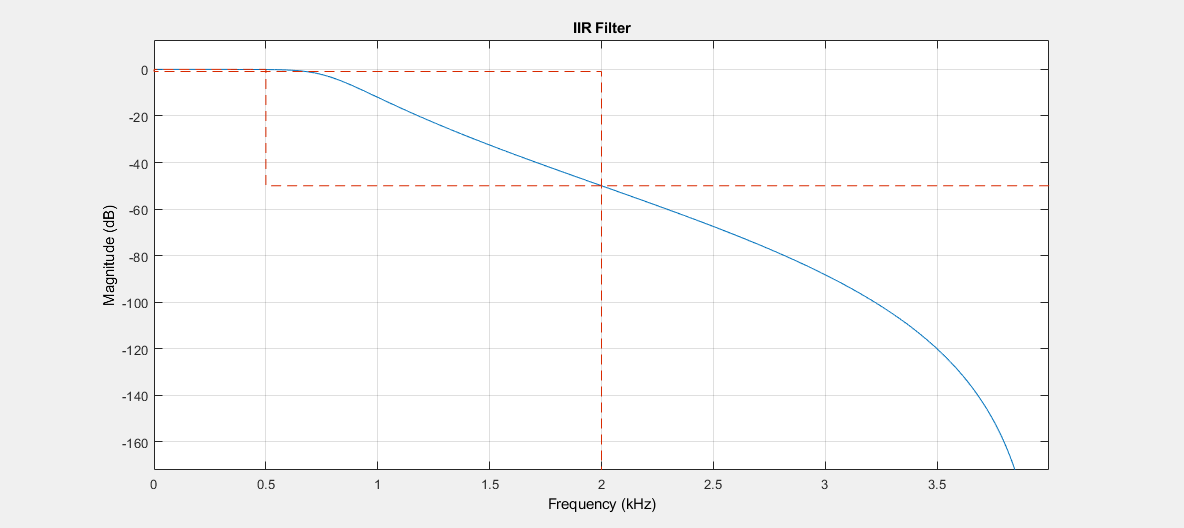

lpFilt_IIR = designfilt('lowpassiir', ...
         'PassbandFrequency',500,'PassbandRipple',0.9, ...
         'StopbandFrequency',2e3,'StopbandAttenuation',50,'SampleRate',8e3);

figure(1);
fvtool(lpFilt_IIR,'magnitude')
title("IIR Filter")

#### (b) Process the signal 𝑥𝑐 (𝑡) through the effective analog system. Generate sufficient samples so the output response 𝑦𝑐 (𝑡)goes into steady state. Plot the steady state 𝑦𝑠𝑠(𝑡) and comment on the filtering result. 

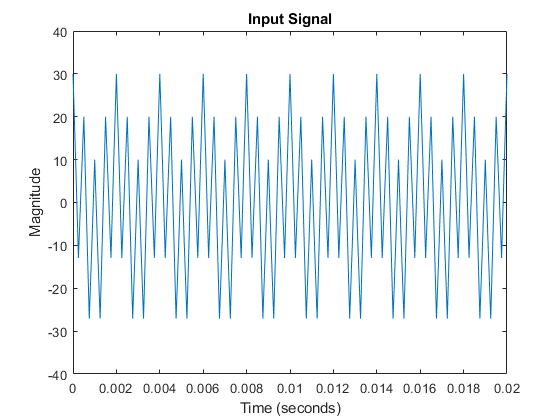

Fs = 8e3;
t = 0:1/Fs:1-1/Fs;

xc =10*cos(1000*pi*t) + 20*cos(4000*pi*t);
figure(2);
plot(t,xc)

xlim([0 0.02])
ylim([-40.0 40.0])
title("Input Signal")
xlabel("Time (seconds)")
ylabel("Magnitude")

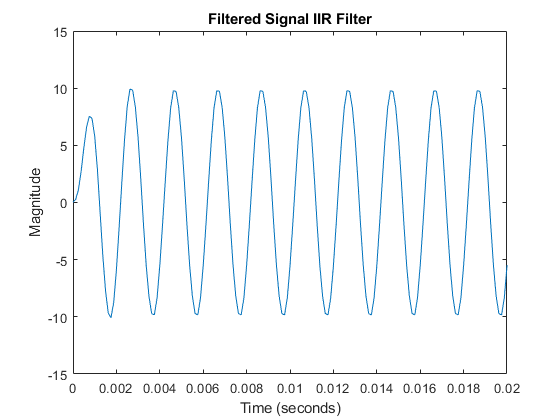

filtered_data_IIR = filter(lpFilt_IIR,xc);

figure(3);
plot(t,filtered_data_IIR)
xlim([0 0.02])
ylim([-15.0 15.0])
title("Filtered Signal IIR Filter")
xlabel("Time (seconds)")
ylabel("Magnitude")

#### (c) Repeat parts (a) and (b) by designing an equiripple FIR filter. Compare the orders of the two filters and their filtering results.

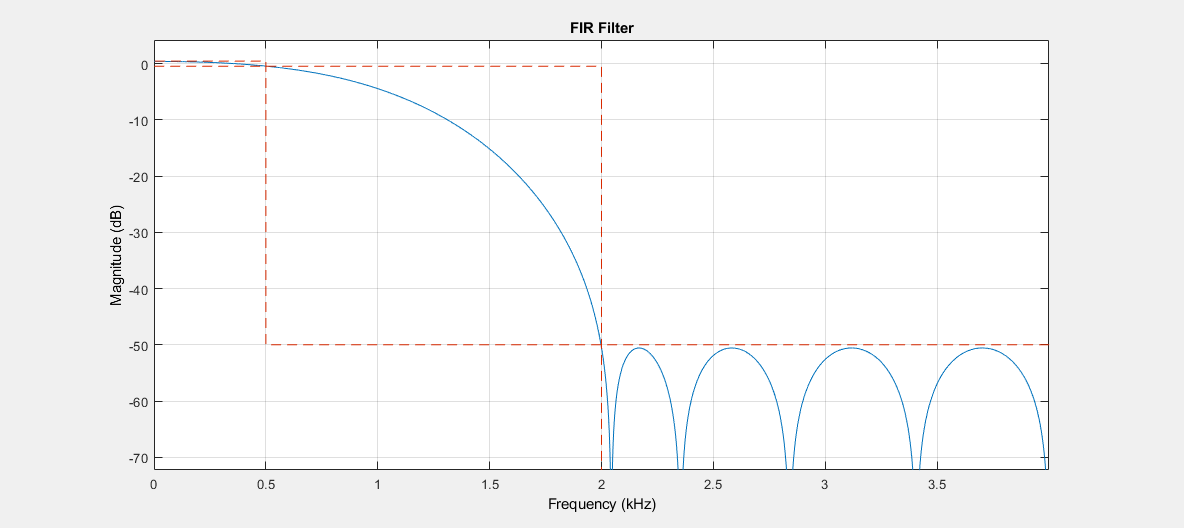

lpFilt_FIR = designfilt('lowpassfir', ...
         'PassbandFrequency',500,'PassbandRipple',0.9, ...
         'StopbandFrequency',2e3,'StopbandAttenuation',50,'SampleRate',8e3);

figure(4);
fvtool(lpFilt_FIR,'magnitude')
title("FIR Filter")

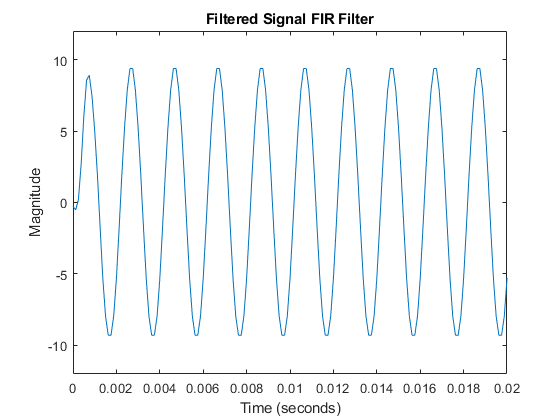

filtered_data_FIR = filter(lpFilt_FIR,xc);

figure(5);
plot(t,filtered_data_FIR)
xlim([0 0.02])
ylim([-12.0 12.0])
title("Filtered Signal FIR Filter")
xlabel("Time (seconds)")
ylabel("Magnitude")

filtord(lpFilt_FIR)

ans = 11

filtord(lpFilt_IIR)

ans = 5

**Order of IIR Filter is 5 and Order of FIR Filter is 11.**

**Also, we can see that IIR Filter in the begenning takes time to adjust to the achieve steady state.**